# playing around with fiber selections

exmining the effect of the SDSS fiber selection effect on galaxy selections 

## loading data and perliminaries

bp=illustris.set_env(100,'nomount');

*** Mounting simulation files *** 
*** cosmolgy for TNG100 has been set: *** 
hub= 0.677 
Omm = 0.31 
Oml= 0.69 
Omb= 0.0486 
***  *** 
*** You are now analyzing the TNG100 Simulation. ENJOY!  *** 


snap=99;
global illUnits
global LBox
global cosmoStruct
units
illustris.utils.set_illUnits(snap);
%loadFofSub;
subsInfo=illustris.infrastructure.build_sub_fof_connection(subs,fofs);

massThresh=10^9;
hostThresh=10^11;

%sampleMask=illustris.infrastructure.generateMask('subs',subs','fofs',fofs,'mass',massThresh,'snap',snap);
centralMask=illustris.infrastructure.generateMask('subs',subs','fofs',fofs,'mass',massThresh,'snap',snap,'centrals');
satMask0=illustris.infrastructure.generateMask('subs',subs','fofs',fofs,'mass',massThresh,'snap',snap,'sats');



hostMass=fofs.Group_M_Crit200(subsInfo.hostFof+1).*illUnits.massUnit;

% this is if you want to enforce host mass cut for identifying centrals
% cenMask=centralMask & hostMass>=hostThresh;
% satMask=satMask0 | (centralMask & ~cenMask ); % includes sat's & centrals of small hosts.

% This is for regular central and satellite identification
cenMask = centralMask;
satMask = satMask0;



sampleMask=cenMask | satMask ;

%rv=fofs.Group_R_Crit200.*illUnits.lengthUnit;
galMass= illustris.utils.get_stellar_mass(subs);


## generate distance measures

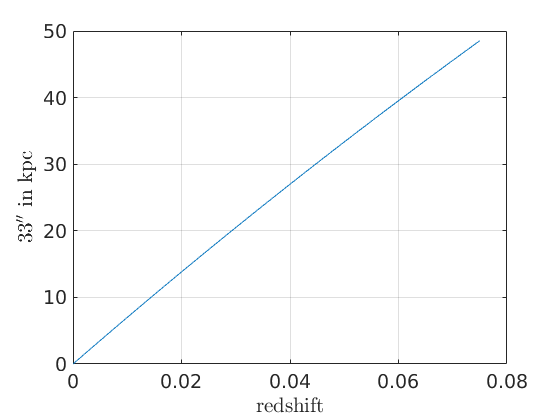

% translate 33'' to kpc
zz=linspace(0,0.075,100);
ang=33/3600*pi/180;
angPhys=ang.*angular_distance(zz,'cosmo',cosmoStruct)*1000; % in kpc

figure
plot(zz,angPhys)
xlabelmine('redshift');
ylabelmine('$33^{\prime\prime}$ in kpc');
grid
set(gca,'fontsize',14)

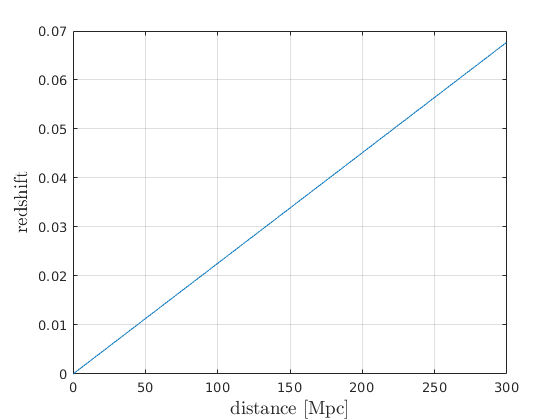


% use hubble law to translate distance to redshift
ll=linspace(0,300,1000); % in Mpc
zl=ll.*(cosmoStruct.hub*100).*Units.km./Units.cspeed;

figure
plot(ll,zl)
grid
xlabelmine('distance [Mpc]' );
ylabelmine('redshift');

## constant aperature 

kk=[2 3 ; 1 3 ; 1 2];
for k=1:3  % loop over projections
    
    % projected distance
    pos(1,:)=double(subs.SubhaloPos(kk(k,1),:)./LBox);
    pos(2,:)=double(subs.SubhaloPos(kk(k,2),:)./LBox);
    pos3=double(subs.SubhaloPos(k,:).*illUnits.lengthUnit)./1000;
    zlen=interp1(ll,zl,pos3,'linear');
    
    % constant aperature for z=0.03
    zpar=0.03;
    lp=interp1(zz,angPhys,zpar,'linear')./(LBox.*illUnits.lengthUnit.*(1/(1+zpar)));
    
    zConst03(k)=sdssFiberSelect(pos,galMass,lp,sampleMask);
    
    % constant aperature for z=0.06
    zpar=0.06;
    lp=interp1(zz,angPhys,zpar,'linear')./(LBox.*illUnits.lengthUnit.*(1/(1+zpar)));
    
    zConst06(k)=sdssFiberSelect(pos,galMass,lp,sampleMask);
    
    % z dependence from z=0.0
    z0=0;
    zpar=z0+zlen;
    lp=interp1(zz,angPhys,zpar,'linear')./(LBox.*illUnits.lengthUnit.*(1/(1+z0)));
    zRun0(k)=sdssFiberSelect(pos,galMass,lp,sampleMask);
    
    % z dependence from z=0.03
    z0=0.03;
    zpar=z0+zlen;
    lp=interp1(zz,angPhys,zpar,'linear')./(LBox.*illUnits.lengthUnit.*(1/(1+z0)));
    zRun03(k)=sdssFiberSelect(pos,galMass,lp,sampleMask);
    
    
end

## plot results for stellar mass  

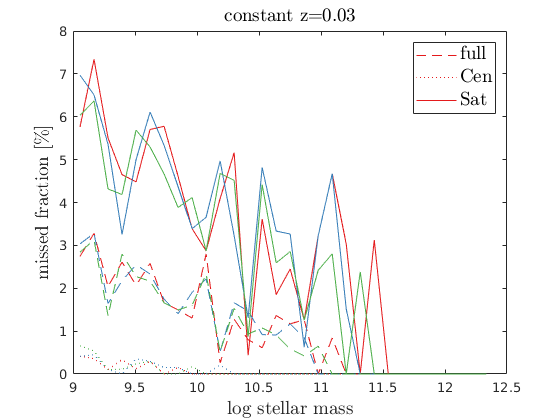

lgmass=log10(galMass);
%edg=linspace(9,12.5,50);
nb=30;

[baseF, edg]=histcounts(lgmass(sampleMask),nb);
[baseC, ~]=histcounts(lgmass(cenMask),nb);
[baseS,~]=histcounts(lgmass(satMask),nb);

bns=0.5.*(edg(1:end-1)+edg(2:end));

colors=brewermap(8,'Set1');

%% constant z 0.03
figure

h=[];
for k=1:3
    numsF=histcounts(lgmass(sampleMask & zConst03(k).outMask),nb);
    numsC=histcounts(lgmass(cenMask & zConst03(k).outMask),nb);
    numsS=histcounts(lgmass(satMask & zConst03(k).outMask),nb);
    h([end+1])=plot(bns,(1-numsF./baseF).*100,'--','color',colors(k,:),...
        'DisplayName','full');
    hold on
    h([end+1])=plot(bns,(1-numsC./baseC).*100,':','color',colors(k,:),...
        'DisplayName','Cen');
    h([end+1])=plot(bns,(1-numsS./baseS).*100,'-','color',colors(k,:),...
        'DisplayName','Sat');
end
legend(h(1:3),'fontsize',14,'Interpreter','latex','location','northeast')
xlabelmine('log stellar mass');
ylabelmine('missed fraction [\%]');
titlemine('constant z=0.03');

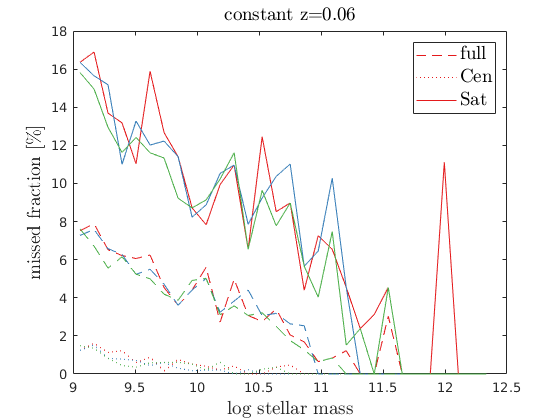


%% constant z 0.06
figure

h=[];
for k=1:3
    numsF=histcounts(lgmass(sampleMask & zConst06(k).outMask),nb);
    numsC=histcounts(lgmass(cenMask & zConst06(k).outMask),nb);
    numsS=histcounts(lgmass(satMask & zConst06(k).outMask),nb);
    h([end+1])=plot(bns,(1-numsF./baseF).*100,'--','color',colors(k,:),...
        'DisplayName','full');
    hold on
    h([end+1])=plot(bns,(1-numsC./baseC).*100,':','color',colors(k,:),...
        'DisplayName','Cen');
    h([end+1])=plot(bns,(1-numsS./baseS).*100,'-','color',colors(k,:),...
        'DisplayName','Sat');
end
legend(h(1:3),'fontsize',14,'Interpreter','latex','location','northeast')
xlabelmine('log stellar mass');
ylabelmine('missed fraction [\%]');
titlemine('constant z=0.06');

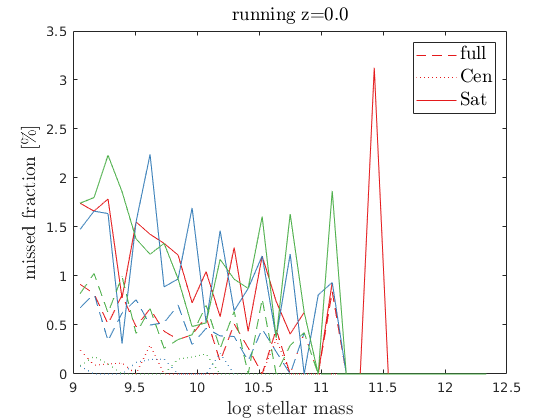


%% running z 0.06
figure

h=[];
for k=1:3
    numsF=histcounts(lgmass(sampleMask & zRun0(k).outMask),nb);
    numsC=histcounts(lgmass(cenMask & zRun0(k).outMask),nb);
    numsS=histcounts(lgmass(satMask & zRun0(k).outMask),nb);
    h([end+1])=plot(bns,(1-numsF./baseF).*100,'--','color',colors(k,:),...
        'DisplayName','full');
    hold on
    h([end+1])=plot(bns,(1-numsC./baseC).*100,':','color',colors(k,:),...
        'DisplayName','Cen');
    h([end+1])=plot(bns,(1-numsS./baseS).*100,'-','color',colors(k,:),...
        'DisplayName','Sat');
end
legend(h(1:3),'fontsize',14,'Interpreter','latex','location','northeast')
xlabelmine('log stellar mass');
ylabelmine('missed fraction [\%]');
titlemine('running z=0.0');

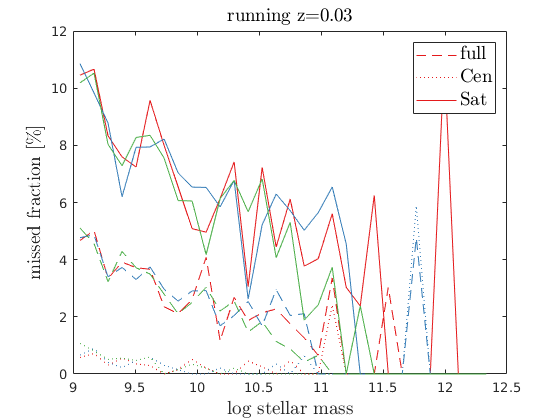


%% running z 0.06
figure

h=[];
for k=1:3
    numsF=histcounts(lgmass(sampleMask & zRun03(k).outMask),nb);
    numsC=histcounts(lgmass(cenMask & zRun03(k).outMask),nb);
    numsS=histcounts(lgmass(satMask & zRun03(k).outMask),nb);
    h([end+1])=plot(bns,(1-numsF./baseF).*100,'--','color',colors(k,:),...
        'DisplayName','full');
    hold on
    h([end+1])=plot(bns,(1-numsC./baseC).*100,':','color',colors(k,:),...
        'DisplayName','Cen');
    h([end+1])=plot(bns,(1-numsS./baseS).*100,'-','color',colors(k,:),...
        'DisplayName','Sat');
end
legend(h(1:3),'fontsize',14,'Interpreter','latex','location','northeast')
xlabelmine('log stellar mass');
ylabelmine('missed fraction [\%]');
titlemine('running z=0.03');

## find missed fractions host by host. 

cnt=0

cnt = 0

missedCentral=false(3,sum(cenMask));
for i=1:length(cenMask)
    aisif ~cenMask(i)
        continue
    end
    cnt=cnt+1;
    % find all satellites of host
    satMaskLoc=subsInfo.hostFof==subsInfo.hostFof(i) & sampleMask;
    satMaskLoc2=satMaskLoc;
    satMaskLoc2(i)=false;
    
    ntot=sum(satMaskLoc);
    ntot2=sum(satMaskLoc2);
    
    for k=1:3
        zc03Missfrac(k,cnt)=1-sum(satMaskLoc & zConst03(k).outMask)./ntot;
        zc03MissSatfrac(k,cnt)=1-sum(satMaskLoc2 & zConst03(k).outMask)./ntot2;
        zc03MissedCentral(k,cnt)=zConst03(k).outMask(i);
        
        zc06Missfrac(k,cnt)=1-sum(satMaskLoc & zConst06(k).outMask)./ntot;
        zc06MissSatfrac(k,cnt)=1-sum(satMaskLoc2 & zConst06(k).outMask)./ntot2;
        zc06MissedCentral(k,cnt)=zConst06(k).outMask(i);
        
        zr0Missfrac(k,cnt)=1-sum(satMaskLoc & zRun0(k).outMask)./ntot;
        zr0MissSatfrac(k,cnt)=1-sum(satMaskLoc2 & zRun0(k).outMask)./ntot2;
        zr0MissedCentral(k,cnt)=zRun0(k).outMask(i);
        
        zr03Missfrac(k,cnt)=1-sum(satMaskLoc & zRun03(k).outMask)./ntot;
        zr03MissSatfrac(k,cnt)=1-sum(satMaskLoc2 & zRun03(k).outMask)./ntot2;
        zr03MissedCentral(k,cnt)=zRun03(k).outMask(i);
        
    end
end
    

%% plot fractions of host mass 

semilogx(hostMass(cenMask),zc06Missfrac(1,:),'.')




% 
% 
% 
%         %satMaskLoc(i)=false; %remove central from
%         
%         
%         lhmass=log10(hostMass);
%         %edg=linspace(9,12.5,50);
%         nb=30;
%         
%         [baseF, edg]=histcounts(lhmass(sampleMask),nb);
%         [baseC, ~]=histcounts(lhmass(cenMask),nb);
%         [baseS,~]=histcounts(lhmass(satMask),nb);
%         
%         bns=0.5.*(edg(1:end-1)+edg(2:end));
%         
%         colors=brewermap(8,'Set1');
%         
%         %% constant z 0.03
%         figure
%         
%         h=[];
%         for k=1:3
%             numsF=histcounts(lhmass(sampleMask & zConst03(k).outMask),nb);
%             numsC=histcounts(lhmass(cenMask & zConst03(k).outMask),nb);
%             numsS=histcounts(lhmass(satMask & zConst03(k).outMask),nb);
%             h([end+1])=plot(bns,(1-numsF./baseF).*100,'--','color',colors(k,:),...
%                 'DisplayName','full');
%             hold on
%             h([end+1])=plot(bns,(1-numsC./baseC).*100,':','color',colors(k,:),...
%                 'DisplayName','Cen');
%             h([end+1])=plot(bns,(1-numsS./baseS).*100,'-','color',colors(k,:),...
%                 'DisplayName','Sat');
%         end
%         legend(h(1:3),'fontsize',14,'Interpreter','latex','location','northeast')
%         xlabelmine('log $M_\mathrm{200,crit}$');
%         ylabelmine('missed fraction [\%]');
%         titlemine('constant z=0.03');
%         
%         %% constant z 0.06
%         figure
%         
%         h=[];
%         for k=1:3
%             numsF=histcounts(lhmass(sampleMask & zConst06(k).outMask),nb);
%             numsC=histcounts(lhmass(cenMask & zConst06(k).outMask),nb);
%             numsS=histcounts(lhmass(satMask & zConst06(k).outMask),nb);
%             h([end+1])=plot(bns,(1-numsF./baseF).*100,'--','color',colors(k,:),...
%                 'DisplayName','full');
%             hold on
%             h([end+1])=plot(bns,(1-numsC./baseC).*100,':','color',colors(k,:),...
%                 'DisplayName','Cen');
%             h([end+1])=plot(bns,(1-numsS./baseS).*100,'-','color',colors(k,:),...
%                 'DisplayName','Sat');
%         end
%         legend(h(1:3),'fontsize',14,'Interpreter','latex','location','northeast')
%         xlabelmine('log $M_\mathrm{200,crit}$');
%         ylabelmine('missed fraction [\%]');
%         titlemine('constant z=0.06');
%         
%         %% running z 0.06
%         figure
%         
%         h=[];
%         for k=1:3
%             numsF=histcounts(lhmass(sampleMask & zRun0(k).outMask),nb);
%             numsC=histcounts(lhmass(cenMask & zRun0(k).outMask),nb);
%             numsS=histcounts(lhmass(satMask & zRun0(k).outMask),nb);
%             h([end+1])=plot(bns,(1-numsF./baseF).*100,'--','color',colors(k,:),...
%                 'DisplayName','full');
%             hold on
%             h([end+1])=plot(bns,(1-numsC./baseC).*100,':','color',colors(k,:),...
%                 'DisplayName','Cen');
%             h([end+1])=plot(bns,(1-numsS./baseS).*100,'-','color',colors(k,:),...
%                 'DisplayName','Sat');
%         end
%         legend(h(1:3),'fontsize',14,'Interpreter','latex','location','northeast')
%         xlabelmine('log $M_\mathrm{200,crit}$');
%         ylabelmine('missed fraction [\%]');
%         titlemine('running z=0.0');
%         
%         %% running z 0.06
%         figure
%         
%         h=[];
%         for k=1:3
%             numsF=histcounts(lhmass(sampleMask & zRun03(k).outMask),nb);
%             numsC=histcounts(lhmass(cenMask & zRun03(k).outMask),nb);
%             numsS=histcounts(lhmass(satMask & zRun03(k).outMask),nb);
%             h([end+1])=plot(bns,(1-numsF./baseF).*100,'--','color',colors(k,:),...
%                 'DisplayName','full');
%             hold on
%             h([end+1])=plot(bns,(1-numsC./baseC).*100,':','color',colors(k,:),...
%                 'DisplayName','Cen');
%             h([end+1])=plot(bns,(1-numsS./baseS).*100,'-','color',colors(k,:),...
%                 'DisplayName','Sat');
%         end
%         legend(h(1:3),'fontsize',14,'Interpreter','latex','location','northeast')
%         xlabelmine('log $M_\mathrm{200,crit}$');
%         ylabelmine('missed fraction [\%]');
%         titlemine('running z=0.03');
%         
% 